# Workshop: Using MATLAB with Python

**Goal:** Use Python code to import current weather data from the web. Predict air quality using MATLAB machine learning model.

## Part 1: Call Python from MATLAB

### Setup

Ensure Python is installed and confirm the version with [`pyenv`](https://mathworks.com/help/matlab/ref/pyenv.html). 

We will provide the path to the correct executable for MATLAB Online.

% pyenv
% pyenv("Version","C:\Python39\python.exe")
% if ~exist("p","var")
%     p = pyenv("Version","/usr/bin/python3")   % for MATLAB Online
% end

*Note: you may need to restart MATLAB if you've already run pyenv and try to change the interpreter.*

*Note: Consider your directories and path needs - often we need to add our directories to both MATLAB and Python paths. *

## 1. Call Python Built-in Functions

Call Python functions using **py.** notation:

Test a simple function.

py.math.sqrt(42)

ans = 6.4807

You can create Python data structures inside MATLAB and call Python methods on them.

py.list({1,2,'a','b'})

ans =   Python list with values:

    [1.0, 2.0, 'a', 'b']

    Use string, double or cell function to convert to a MATLAB array.


Pass name=value arguments using similar syntax (beginning in release R2022a)

py.textwrap.wrap("Hello world!",width=int8(2))    % convert to integer

ans =   Python list with values:

    ['He', 'll', 'o ', 'wo', 'rl', 'd!']

    Use string, double or cell function to convert to a MATLAB array.


*Hint: Consider default and expected data types*

### Exercise 1: Call a Built-in Python Function

Try out some more Python built-in functions below:

%% Write code here
py.urllib.parse.urlparse(...
    "http://samples.openweathermap.org/data/2.5/weather?q=London\u0026appid=b1b15e88fa797225412429c1c50c122a1")

ans =   Python ParseResult with properties:

    fragment
    hostname
    netloc
    params
    password
    path
    port
    query
    scheme
    username

    ParseResult(scheme='http', netloc='samples.openweathermap.org', path='/data/2.5/weather', params='', query='q=London\\u0026appid=b1b15e88fa797225412429c1c50c122a1', fragment='')


py.help("list")

Help on class list in module builtins:

class list(object)
 |  list(iterable=(), /)
 |  
 |  Built-in mutable sequence.
 |  
 |  If no argument is given, the constructor creates a new empty list.
 |  The argument must be an iterable if specified.
 |  
 |  Methods defined here:
 |  
 |  __add__(self, value, /)
 |      Return self+value.
 |  
 |  __contains__(self, key, /)
 |      Return key in self.
 |  
 |  __delitem__(self, key, /)
 |      Delete self[key].
 |  
 |  __eq__(self, value, /)
 |      Return self==value.
 |  
 |  __ge__(self, value, /)
 |      Return self>=value.
 |  
 |  __getattribute__(self, name, /)
 |      Return getattr(self, name).
 |  
 |  __getitem__(...)
 |      x.__getitem__(y) <==> x[y]
 |  
 |  __gt__(self, value, /)
 |      Return self>value.
 |  
 |  __iadd__(self, value, /)
 |      Implement self+=value.
 |  
 |  __imul__(self, value, /)
 |      Implement self*=value.
 |  
 |  __init__(self, /, *args, **kwargs)
 |      Initialize self.  See help(type(self))

a = py.importlib.import_module("this")

The Zen of Python, by Tim Peters

Beautiful is better than ugly.
Explicit is better than implicit.
Simple is better than complex.
Complex is better than complicated.
Flat is better than nested.
Sparse is better than dense.
Readability counts.
Special cases aren't special enough to break the rules.
Although practicality beats purity.
Errors should never pass silently.
Unless explicitly silenced.
In the face of ambiguity, refuse the temptation to guess.
There should be one-- and preferably only one --obvious way to do it.
Although that way may not be obvious at first unless you're Dutch.
Now is better than never.
Although never is often better than *right* now.
If the implementation is hard to explain, it's a bad idea.
If the implementation is easy to explain, it may be a good idea.
Namespaces are one honking great idea -- let's do more of those!


a =   Python module with properties:

    i: [1×1 py.int]
    d: [1×1 py.dict]
    c: [1×1 py.int]
    s: [1×856 py.str]

    <module 'this' from 'C:\\tkyung\\MW\\Demos\\!Resources\\WPy64-31090\\python-3.10.9.amd64\\lib\\this.py'>


## 2. Call User Defined Python Code

There are several ways to call user-defined Python code from MATLAB, depending on how the code is prepared.

Use [`pyrun`](https://mathworks.com/help/matlab/ref/pyrun.html) to execute python statements and [`pyrunfile`](https://mathworks.com/help/matlab/ref/pyrunfile.html) to run a Python script file. 

### Run Python Script

First, examine the code then run the script using pyrunfile.

pyrunfile("weather_script.py")

Displaying temperature for: Boston
The temperature is 37.06


Capture outputs from the script.

t = pyrunfile("weather_script.py","t")

Displaying temperature for: Boston
The temperature is 39.54


t = 39.5400

### Exercise 2.1: Run Python Script

Modify `weather_script.py` line 21 to display info for a different city and call it from MATLAB.

%% Write code here
[t,w] = pyrunfile("weather_script.py",["t","w"])

Displaying temperature for: Boston
The temperature is 44.1


t = 44.1000

w =   Python str with no properties.

    Boston


### Call Python Module

To call a module from MATLAB, we use this syntax

*Note: When you modify a module, you need to reload it for the changes to take effect. See the Appendix below for an example. *[*Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)*](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

### Call Weather Module

The `weather.py` module reads and parses current weather data from the web API by location: [https://openweathermap.org/api](https://openweathermap.org/api)

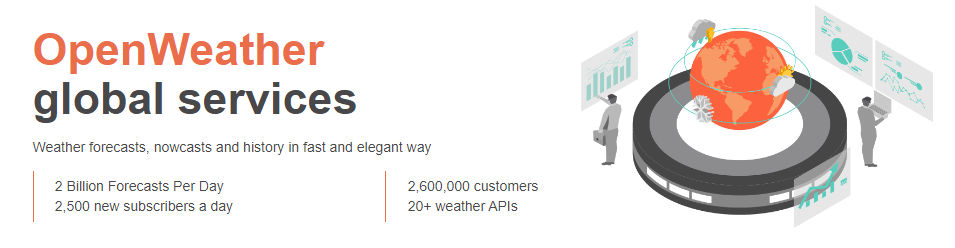

First, get the access key for the weather API.

apikey = readtable("accessKey.txt","TextType","string"); 

Use the `weather.py` module to get the current weather data.

%% Write code here
city = "Boston";
jsonData = py.weather.get_current_weather(city,"US",apikey.Key)

jsonData =   Python dict with no properties.

    {'coord': {'lon': -71.0598, 'lat': 42.3584}, 'weather': [{'id': 803, 'main': 'Clouds', 'description': 'broken clouds', 'icon': '04d'}], 'base': 'stations', 'main': {'temp': 83.19, 'feels_like': 86.94, 'temp_min': 77.95, 'temp_max': 86.45, 'pressure': 1018, 'humidity': 63}, 'visibility': 10000, 'wind': {'speed': 13.8, 'deg': 190}, 'clouds': {'all': 75}, 'dt': 1690232295, 'sys': {'type': 1, 'id': 3486, 'country': 'US', 'sunrise': 1690190907, 'sunset': 1690243962}, 'timezone': -14400, 'id': 4930956, 'name': 'Boston', 'cod': 200}


Parse the json data returned from the weather API.

weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 83.19, 'feels_like': 86.94, 'temp_min': 77.95, 'temp_max': 86.45, 'pressure': 1018, 'humidity': 63, 'speed': 13.8, 'deg': 190, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2023-07-24 13:59:26.577272'}


Extract the values from the dictionary. 

weatherData{"temp"}

ans = 83.1900

### Exercise 2.2: What is the Forecast? 

Now, use the following syntax to call the `get_forecast` function from the weather module:

%% Write code here
jsonData = py.weather.get_forecast(city,"US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData)

forecastData =   Python dict with no properties.

    {'current_time': ['2023-07-24 21:00:00', '2023-07-25 00:00:00', '2023-07-25 03:00:00', '2023-07-25 06:00:00', '2023-07-25 09:00:00', '2023-07-25 12:00:00', '2023-07-25 15:00:00', '2023-07-25 18:00:00', '2023-07-25 21:00:00', '2023-07-26 00:00:00', '2023-07-26 03:00:00', '2023-07-26 06:00:00', '2023-07-26 09:00:00', '2023-07-26 12:00:00', '2023-07-26 15:00:00', '2023-07-26 18:00:00', '2023-07-26 21:00:00', '2023-07-27 00:00:00', '2023-07-27 03:00:00', '2023-07-27 06:00:00', '2023-07-27 09:00:00', '2023-07-27 12:00:00', '2023-07-27 15:00:00', '2023-07-27 18:00:00', '2023-07-27 21:00:00', '2023-07-28 00:00:00', '2023-07-28 03:00:00', '2023-07-28 06:00:00', '2023-07-28 09:00:00', '2023-07-28 12:00:00', '2023-07-28 15:00:00', '2023-07-28 18:00:00', '2023-07-28 21:00:00', '2023-07-29 00:00:00', '2023-07-29 03:00:00', '2023-07-29 06:00:00', '2023-07-29 09:00:00', '2023-07-29 1

% Get the current time
forecastData{'current_time'}

ans =   Python list with values:

    ['2023-07-24 21:00:00', '2023-07-25 00:00:00', '2023-07-25 03:00:00', '2023-07-25 06:00:00', '2023-07-25 09:00:00', '2023-07-25 12:00:00', '2023-07-25 15:00:00', '2023-07-25 18:00:00', '2023-07-25 21:00:00', '2023-07-26 00:00:00', '2023-07-26 03:00:00', '2023-07-26 06:00:00', '2023-07-26 09:00:00', '2023-07-26 12:00:00', '2023-07-26 15:00:00', '2023-07-26 18:00:00', '2023-07-26 21:00:00', '2023-07-27 00:00:00', '2023-07-27 03:00:00', '2023-07-27 06:00:00', '2023-07-27 09:00:00', '2023-07-27 12:00:00', '2023-07-27 15:00:00', '2023-07-27 18:00:00', '2023-07-27 21:00:00', '2023-07-28 00:00:00', '2023-07-28 03:00:00', '2023-07-28 06:00:00', '2023-07-28 09:00:00', '2023-07-28 12:00:00', '2023-07-28 15:00:00', '2023-07-28 18:00:00', '2023-07-28 21:00:00', '2023-07-29 00:00:00', '2023-07-29 03:00:00', '2023-07-29 06:00:00', '2023-07-29 09:00:00', '2023-07-29 12:00:00', '2023-07-29 15:00:00', 

Note the data types returned, which we will examine next.

## 3. Convert to MATLAB Data Types

Now we want to operate on this data in MATLAB, so the next step is to convert the data types as needed. There is a table in the doc with the data types listed: [**MATLAB to Python Data Type Mapping**](https://uk.mathworks.com/help/matlab/matlab_external/passing-data-to-python.html)

### Convert Weather Data

Now, we'll get back to converting our weather data which is a dictionary containing mixed data types. 

weatherData

weatherData =   Python dict with no properties.

    {'temp': 83.19, 'feels_like': 86.94, 'temp_min': 77.95, 'temp_max': 86.45, 'pressure': 1018, 'humidity': 63, 'speed': 13.8, 'deg': 190, 'lon': -71.0598, 'lat': 42.3584, 'city': 'Boston', 'current_time': '2023-07-24 13:59:26.577272'}


The **Python dictionary** can be represented as a **MATLAB struct**.

data = struct(weatherData)

data = struct with fields:
            temp: 83.1900
      feels_like: 86.9400
        temp_min: 77.9500
        temp_max: 86.4500
        pressure: [1×1 py.int]
        humidity: [1×1 py.int]
           speed: 13.8000
             deg: [1×1 py.int]
             lon: -71.0598
             lat: 42.3584
            city: [1×6 py.str]
    current_time: [1×26 py.str]


Convert the Python types within the struct to the desired MATLAB data types.

data.pressure = double(data.pressure);
data.city = string(data.city)

data = struct with fields:
            temp: 83.1900
      feels_like: 86.9400
        temp_min: 77.9500
        temp_max: 86.4500
        pressure: 1018
        humidity: [1×1 py.int]
           speed: 13.8000
             deg: [1×1 py.int]
             lon: -71.0598
             lat: 42.3584
            city: "Boston"
    current_time: [1×26 py.str]


### Exercise 3: Convert Weather Data

Convert remaining Python types to MATLAB types.

%% Write code here
data.humidity = double(data.humidity);
data.deg = double(data.deg);
data.current_time = string(data.current_time);

Perform the remaining conversions and create a table using the function provided to prep for machine learning.

currentData = prepData(weatherData)

currentData = 1×12 table
         DateLocal            city        StateName        T       P       DP      RH    WindDir    WindSpd     yy     MM    dd
    ____________________    ________    _____________    _____    ____    _____    __    _______    _______    ____    __    __

    24-Jul-2023 13:59:26    "Boston"    Massachusetts    83.19    1018    69.87    63      190       13.8      2023    7     24


## 4. Predict Air Quality

A machine learning model has been trained and validated on a large amount of historical climate data. The model is then saved as a .mat file. 

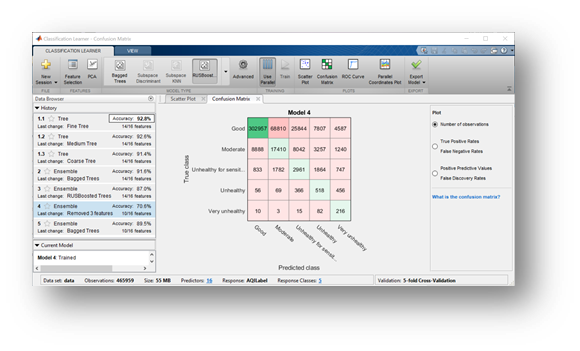

Use the model to predict the air quality for the new weather data.

load airQualModel 
airQual = predict(model,currentData)

airQual = categorical
     Unhealthy 


### Exercise 4: Predict Air Quality

Test the prediction code in MATLAB for different locations. The function `predictAirQual.m `captures the previous steps (to be tested and later called from Python)

city = "San%20Jose";
jsonData = py.weather.get_current_weather(city,"US",apikey.Key);
weatherData = py.weather.parse_current_json(jsonData)

weatherData =   Python dict with no properties.

    {'temp': 83.93, 'feels_like': 83.53, 'temp_min': 69.51, 'temp_max': 93.9, 'pressure': 1017, 'humidity': 42, 'speed': 12.66, 'deg': 350, 'lon': -121.895, 'lat': 37.3394, 'city': 'San Jose', 'current_time': '2023-07-24 13:59:29.985855'}


predictAirQual(weatherData)

ans = 'Moderate'

## 5. Bonus: Manage Arrays of Weather Forecast Data

Now let's look at the weather forecast for this week!

city = "San%20Jose";
jsonData = py.weather.get_forecast(city,"US",apikey.Key);
forecastData = py.weather.parse_forecast_json(jsonData);
forecast = struct(forecastData)

forecast = struct with fields:
    current_time: [1×40 py.list]
            temp: [1×40 py.list]
             deg: [1×40 py.list]
           speed: [1×40 py.list]
        humidity: [1×40 py.list]
        pressure: [1×40 py.list]


The type of data returned by the parsed forecast date is a **Python list**:

forecast.temp

ans =   Python list with values:

    [84.0, 84.87, 76.15, 64.22, 62.6, 61.74, 70.81, 85.87, 95.27, 91.74, 76.78, 67.87, 65.53, 63.28, 70.92, 86.49, 93.63, 89.2, 72.19, 63.01, 60.44, 58.86, 66.58, 82.56, 89.96, 85.06, 70.65, 61.66, 59.45, 58.57, 67.39, 83.12, 90.86, 86.04, 70.23, 61.39, 58.69, 56.55, 63.88, 79.81]

    Use string, double or cell function to convert to a MATLAB array.


It can be converted to a matrix of doubles:

tempForecast = double(forecast.temp)         

tempForecast =    84.0000   84.8700   76.1500   64.2200   62.6000   61.7400   70.8100   85.8700   95.2700   91.7400   76.7800   67.8700   65.5300   63.2800   70.9200   86.4900   93.6300   89.2000   72.1900   63.0100   60.4400   58.8600   66.5800   82.5600   89.9600   85.0600   70.6500   61.6600   59.4500   58.5700   67.3900   83.1200   90.8600   86.0400   70.2300   61.3900   58.6900   56.5500   63.8800   79.8100


Transform **timestamp list** from Python in **MATLAB datetime**:

T = string(forecast.current_time)

T = 1×40 string array
    "2023-07-24 21:00:00"    "2023-07-25 00:00:00"    "2023-07-25 03:00:00"    "2023-07-25 06:00:00"    "2023-07-25 09:00:00"    "2023-07-25 12:00:00"    "2023-07-25 15:00:00"    "2023-07-25 18:00:00"    "2023-07-25 21:00:00"    "2023-07-26 00:00:00"    "2023-07-26 03:00:00"    "2023-07-26 06:00:00"    "2023-07-26 09:00:00"    "2023-07-26 12:00:00"    "2023-07-26 15:00:00"    "2023-07-26 18:00:00"    "2023-07-26 21:00:00"    "2023-07-27 00:00:00"    "2023-07-27 03:00:00"    "2023-07-27 06:00:00"    "2023-07-27 09:00:00"    "2023-07-27 12:00:00"    "2023-07-27 15:00:00"    "2023-07-27 18:00:00"    "2023-07-27 21:00:00"    "2023-07-28 00:00:00"    "2023-07-28 03:00:00"    "2023-07-28 06:00:00"    "2023-07-28 09:00:00"    "2023-07-28 12:00:00"    "2023-07-28 15:00:00"    "2023-07-28 18:00:00"    "2023-07-28 21:00:00"    "2023-07-29 00:00:00"    "2023-07-29 03:00:00"    "2023-07-29 06:00:00"    "2023-07-29 09:00:00"    "2023-07-29 12:00:00"    "2023-07-29 15:00:00"   

Convert T in datetime and plot

time = datetime(T)

time = 1×40 datetime array
   24-Jul-2023 21:00:00   25-Jul-2023 00:00:00   25-Jul-2023 03:00:00   25-Jul-2023 06:00:00   25-Jul-2023 09:00:00   25-Jul-2023 12:00:00   25-Jul-2023 15:00:00   25-Jul-2023 18:00:00   25-Jul-2023 21:00:00   26-Jul-2023 00:00:00   26-Jul-2023 03:00:00   26-Jul-2023 06:00:00   26-Jul-2023 09:00:00   26-Jul-2023 12:00:00   26-Jul-2023 15:00:00   26-Jul-2023 18:00:00   26-Jul-2023 21:00:00   27-Jul-2023 00:00:00   27-Jul-2023 03:00:00   27-Jul-2023 06:00:00   27-Jul-2023 09:00:00   27-Jul-2023 12:00:00   27-Jul-2023 15:00:00   27-Jul-2023 18:00:00   27-Jul-2023 21:00:00   28-Jul-2023 00:00:00   28-Jul-2023 03:00:00   28-Jul-2023 06:00:00   28-Jul-2023 09:00:00   28-Jul-2023 12:00:00   28-Jul-2023 15:00:00   28-Jul-2023 18:00:00   28-Jul-2023 21:00:00   29-Jul-2023 00:00:00   29-Jul-2023 03:00:00   29-Jul-2023 06:00:00   29-Jul-2023 09:00:00   29-Jul-2023 12:00:00   29-Jul-2023 15:00:00   29-Jul-2023 18:00:00


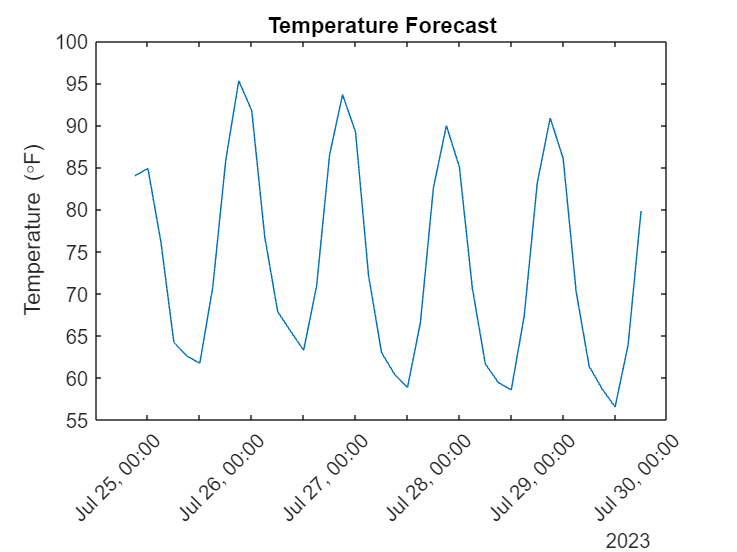

plot(time,tempForecast)
xtickangle(45)
title("Temperature Forecast")
ylabel("Temperature (\circF)")

### Bonus: Preprocess Data Using Live Editor Tasks

Go to the Tasks buttom in the Live Editor toolstrip and select Create Plot

## Insert plot task here

foreTemp = timetable(time',tempForecast','VariableNames',{'Temperature'});

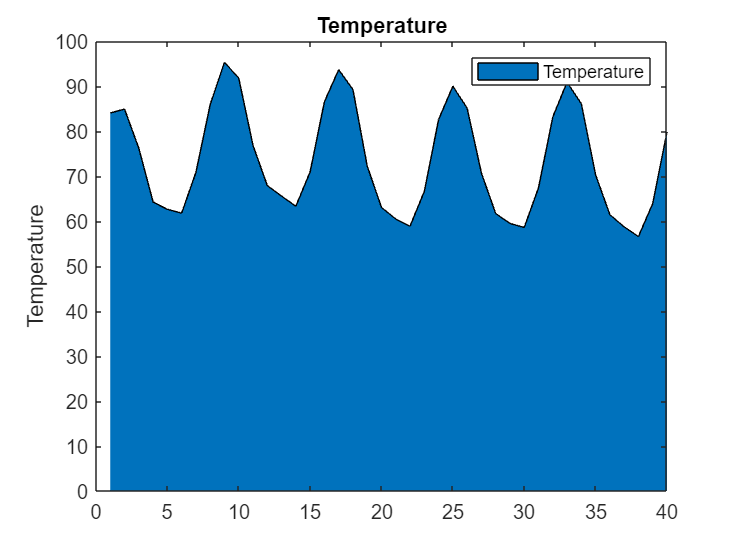

% Create area of foreTemp.Temperature
ar = area(foreTemp.Temperature,"DisplayName","Temperature");

% Add ylabel, title, and legend
ylabel("Temperature")
title("Temperature")
legend

Weather forecasts are only provided every 4 hours. We want to retime to have data interpolated every single hour.

% Retime timetable
newTimetable = retime(foreTemp,"regular","spline","TimeStep",hours(3))

newTimetable = 40×1 timetable
            Time            Temperature
    ____________________    ___________

    24-Jul-2023 21:00:00          84   
    25-Jul-2023 00:00:00       84.87   
    25-Jul-2023 03:00:00       76.15   
    25-Jul-2023 06:00:00       64.22   
    25-Jul-2023 09:00:00        62.6   
    25-Jul-2023 12:00:00       61.74   
    25-Jul-2023 15:00:00       70.81   
    25-Jul-2023 18:00:00       85.87   
    25-Jul-2023 21:00:00       95.27   
    26-Jul-2023 00:00:00       91.74   
    26-Jul-2023 03:00:00       76.78   
    26-Jul-2023 06:00:00       67.87   
    26-Jul-2023 09:00:00       65.53   
    26-Jul-2023 12:00:00       63.28   
    26-Jul-2023

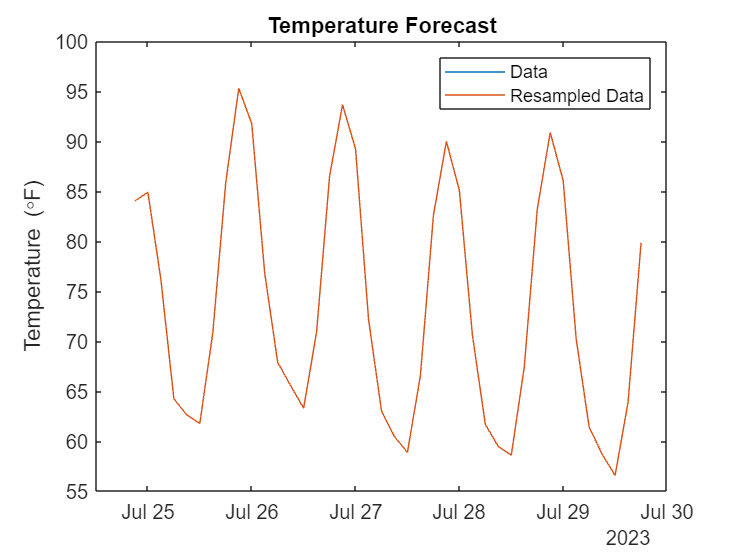

plot(foreTemp.Time,foreTemp.Temperature); hold on
plot(newTimetable.Time,newTimetable.Temperature); hold off
legend("Data","Resampled Data")
title("Temperature Forecast")
ylabel("Temperature (\circF)")

Select different trend removal parameters and examine the results.

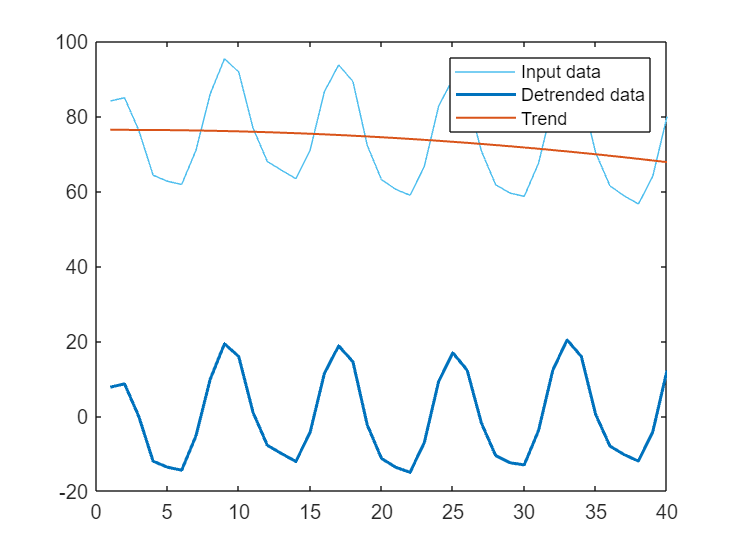

% Remove trend from data
detrendedData = detrend(tempForecast,2);

% Display results
clf
plot(tempForecast,"Color",[77 190 238]/255,"DisplayName","Input data")
hold on
plot(detrendedData,"Color",[0 114 189]/255,"LineWidth",1.5,...
    "DisplayName","Detrended data")
plot(tempForecast-detrendedData,"Color",[217 83 25]/255,"LineWidth",1,...
    "DisplayName","Trend")
hold off
legend

There are a number of Live Editor Tasks you can add to this script to continue to clean the data (smooth, remove outliers, etc.). Try these out for yourself!

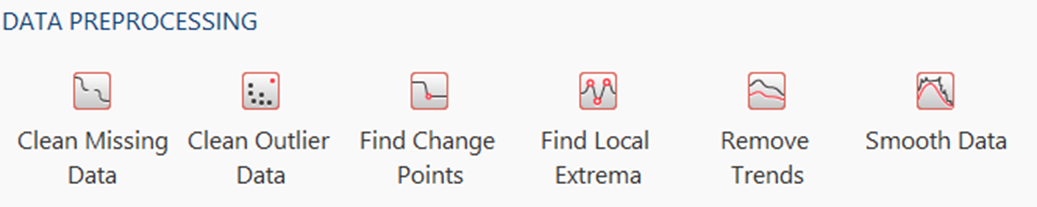

## Part 2: Call MATLAB Prediction Code from Python

Call a function capturing these steps and the correct data conversions to be called in the Python environment to predict the air quality. See `predictAirQual.m`

% edit("predictAirQual.m")

Next, we will call this code from Python using the [MATLAB Engine API for Python](https://mathworks.com/help/matlab/matlab-engine-for-python.html). See `CallMATLABfromPython.ipynb `for the next steps. 

## Appendix

[Cheatsheets for Using MATLAB with Python](https://mathworks.com/campaigns/offers/matlab-python-cheat-sheets.html) 

Documentation and troubleshooting info: [Calling Python from MATLAB](https://mathworks.com/help/matlab/call-python-libraries.html)

Reloading Python modules

Reload *weather.py *after modifications:

% clear classes
% mod = py.importlib.import_module('weather'); 
% py.importlib.reload(mod); 

Read the documentation to know more:

[Reload Modified User-Defined Python Module - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/matlab/matlab_external/call-modified-python-module.html)

*Copyright 2022 - 2023 The MathWorks, Inc.*